## Data Input 


clear all;
close all;
colors=npg(10); % Ten basic colors 
maindir=['\\Artemis-pc\Data\2026-03-31\Abs-81' ...
    '\'];
main_dir_0=maindir;
load([maindir,'\population.mat']);
%load([maindir,'\Fit.mat']);


## Precession 

不同秒数下进动

close all;

ROT = 0;   % 是否ROT曲线
dual_Ramsey = 0;    % 是否有两种同位素
first_species = 171;   % 第1、2张照片拍的元素，171或173
delete_odd = 0;    % 是否删除异常组
plot_all = 0;    % 是否画所有曲线
offset = 0;    % 拟合是否考虑sin曲线上下非对称
plot_contrast = 0;    % 是否画对比度曲线
cross_zero = 0;    % 是否标注共同过零点，需两种同位素，且不考虑曲线offset

coefficient = 2;   % 当前磁场和10mGauss的比值

%x1 = [0 1.25 2.5 3.6 5:1.25:25];
x1 = 6;
xlist = [7:7:98];

x_label = 'Precession (ms)';
%x_label = 'z-Rotation (us)';
if ROT == 1
    x_label = 'Rotation (us)';
end

y_lim_low = -1;
y_lim_high = 1;

x_lim_low = min(xlist);
x_lim_high = max(xlist);

relativeOD = (s1-s2)./(s1+s2);
%relativeOD = (s3-s4)./(s3+s4);
repeat_se = length(relativeOD)/(length(x1)*length(xlist));
reshape_phase = reshape(relativeOD,length(xlist),repeat_se,length(x1));

if dual_Ramsey == 1

    relativeOD2 = (s3-s4)./(s3+s4);
    repeat_se2 = length(relativeOD2)/(length(x1)*length(xlist));
    reshape_phase2 = reshape(relativeOD2,length(xlist),repeat_se2,length(x1));

end



if plot_all == 1
    for k = 1:length(x1)

        figure;hold on;
        for i = 1:repeat_se
            plot(xlist,reshape_phase(:,i,k),'*-');
            ylim([y_lim_low y_lim_high]);
        end
        legend('Location','best');
        hold off;

        if dual_Ramsey == 1
            title(['Yb-173 ',num2str(x1(k)),'s']);

            figure;hold on;
            for i = 1:repeat_se2
                plot(xlist,reshape_phase2(:,i,k),'*-');
                ylim([y_lim_low y_lim_high]);
            end
            legend('Location','best');

            title(['Yb-171 ',num2str(x1(k)),'s']);

            hold off;

        end

    end
end


## Average


reduce_index = 0;  % 舍弃前几组

%xlist(451:end) = [];

aver_phase = zeros(size(reshape_phase,1) , repeat_se-reduce_index , size(reshape_phase,3));
aver_phase = reshape_phase(:,(reduce_index+1):repeat_se,:);

phase_mean = mean(aver_phase,2);
phase_std = std(aver_phase,0,2);
phase_weight = 1./(phase_std).^2;

if dual_Ramsey == 1

    reduce_index2 = 0;  % 舍弃前几组

    aver_phase2 = zeros(size(reshape_phase2,1) , repeat_se2-reduce_index2 , size(reshape_phase2,3));
    aver_phase2 = reshape_phase2(:,(reduce_index2+1):repeat_se2,:);

    phase_mean2 = mean(aver_phase2,2);
    phase_std2 = std(aver_phase2,0,2);
    phase_weight2 = 1./(phase_std2).^2;

end


## 排除异常组


if delete_odd == 1

%     % 80s %
%     temp_phase = aver_phase(:,:,6);    % Precession = x1(6)s 存在异常组
%     temp_phase(:,1) = [];   % Precession = x1(6)s 的第一组异常，删除
% 
%     phase_mean(:,:,6) = mean(temp_phase,2);
%     phase_std(:,:,6) = std(temp_phase,0,2);
%     phase_weight2(:,:,6) = 1./(phase_std2(:,:,6)).^2;
% 
%     % 100s %
%     temp_phase = aver_phase(:,:,7);
%     temp_phase(:,2) = [];
% 
%     phase_mean(:,:,7) = mean(temp_phase,2);
%     phase_std(:,:,7) = std(temp_phase,0,2);
%     phase_weight2(:,:,7) = 1./(phase_std2(:,:,7)).^2;


    % Yb-171 %
    if dual_Ramsey == 1

        % 60s %
        temp_phase2 = aver_phase2(:,:,1);
        temp_phase2(:,2) = [];

        phase_mean2(:,:,1) = mean(temp_phase2,2);
        phase_std2(:,:,1) = ones(size(temp_phase2,1),1);
        phase_weight2(:,:,1) = 1./(phase_std2(:,:,1)).^2;

%         % 80s %
%         temp_phase2 = aver_phase2(:,:,6);
%         temp_phase2(:,1) = [];
% 
%         phase_mean2(:,:,6) = mean(temp_phase2,2);
%         phase_std2(:,:,6) = std(temp_phase2,0,2);
%         phase_weight2(:,:,6) = 1./(phase_std2(:,:,6)).^2;
% 
%         % 100s %
%         temp_phase = aver_phase(:,:,7);
%         temp_phase(:,3) = [];
% 
%         phase_mean(:,:,7) = mean(temp_phase,2);
%         phase_std(:,:,7) = std(temp_phase,0,2);
%         phase_weight2(:,:,7) = 1./(phase_std2(:,:,7)).^2;

    end

end


## Average Plot

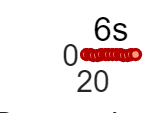


if dual_Ramsey == 0

    for k = 1:length(x1)

        figure;
        I_se = errorbar(xlist,phase_mean(:,k),1.*phase_std(:,k)./sqrt(repeat_se-1),'o-');


        xlabel(x_label);
        %ylabel('OD 2/OD 1');
        %ylabel('OD 2');
        ylabel('S_z');
        title([num2str(x1(k)),'s']);

        set(gca,'FontSize',18);
        xlim([x_lim_low x_lim_high]);
        ylim([y_lim_low y_lim_high]);

        I_se.CapSize = 0;
        I_se.MarkerSize = 50;
        I_se.LineWidth = 2;
        I_se.Color = [0.5,0.4,0.3];
        I_se.MarkerSize = 6;
        I_se.MarkerEdgeColor = [0.7 0 0];
        I_se.MarkerFaceColor = [1 0.6 0.5];

    end

end


if dual_Ramsey == 1

    for k = 1:length(x1)

        figure;hold on;
        I_se1 = errorbar(xlist,phase_mean(:,k),1.*phase_std(:,k)./sqrt(repeat_se-1),'o-');
        I_se2 = errorbar(xlist,phase_mean2(:,k),1.*phase_std2(:,k)./sqrt(repeat_se2-1),'o-');


        xlabel(x_label);
        ylabel('S_z');
        title([num2str(x1(k)),'s']);
        legend('Yb-173','Yb-171','Location','best')

        set(gca,'FontSize',18);
        xlim([x_lim_low x_lim_high]);
        ylim([y_lim_low y_lim_high]);

        I_se1.CapSize=0;
        I_se1.MarkerSize=50;
        I_se1.LineWidth=2;
        I_se1.Color=[0.45,0.63,0.67];
        I_se1.MarkerSize=6;
        I_se1.MarkerEdgeColor=[0.04,0.59,0.83];
        I_se1.MarkerFaceColor=[0.29,0.91,0.91];

        I_se2.CapSize = 0;
        I_se2.MarkerSize = 50;
        I_se2.LineWidth = 2;
        I_se2.Color = [0.5,0.4,0.3];
        I_se2.MarkerSize = 6;
        I_se2.MarkerEdgeColor = [0.7 0 0];
        I_se2.MarkerFaceColor = [1 0.6 0.5];

        hold off;

    end

end


## Fit

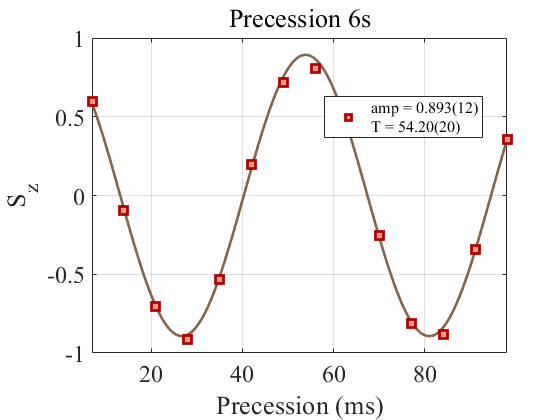


for k = 1:length(x1)

    if repeat_se == 1
        [xData, yData] = prepareCurveData(xlist,phase_mean(:,:,k));
        weight = ones(length(xData),1);
    else
        [xData, yData, weight] = prepareCurveData(xlist,phase_mean(:,:,k),phase_weight(:,:,k));
    end

    if offset == 1

        % 设置 fittype 和选项。
        ft = fittype( 'a*sin(2*pi*x/T+b)+c', 'independent', 'x', 'dependent', 'y' );
        opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
        opts.Display = 'Off';
        if first_species == 171
            opts.Lower = [95/coefficient 0.01 -2*pi -5];
            opts.Upper = [125/coefficient 1 2*pi 5];
            opts.StartPoint = [108/coefficient 0.5 0.9 0.9];
        elseif first_species == 173
            opts.Lower = [65/coefficient 0.01 -2*pi -5];
            opts.Upper = [95/coefficient 1 2*pi 5];
            opts.StartPoint = [78/coefficient 0.5 0.9 0.9];
        end
        opts.Weights = weight;

        % 对数据进行模型拟合。
        [fitresult, gof] = fit(xData, yData, ft, opts);
        amp(k) = fitresult.a;
        T(k) = fitresult.T;
        c(k) = fitresult.c;
        interval = confint(fitresult);
        a_sigma(k) = (interval(2,2)-interval(1,2))/4;
        T_sigma(k) = (interval(2,1)-interval(1,1))/4;
        c_sigma(k) = (interval(2,4)-interval(1,4))/4;

    elseif offset == 0

        % 设置 fittype 和选项。
        ft = fittype( 'a*sin(2*pi*x/T+b)', 'independent', 'x', 'dependent', 'y' );
        opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
        opts.Display = 'Off';

        if first_species == 171
            opts.Lower = [95/coefficient 0.01 -2*pi];
            opts.Upper = [125/coefficient 1 2*pi];
            opts.StartPoint = [108/coefficient 0.5 0.9];
        elseif first_species == 173
            opts.Lower = [65/coefficient 0.01 -2*pi];
            opts.Upper = [95/coefficient 1 2*pi];
            opts.StartPoint = [78/coefficient 0.5 0.9];
        end
        
        opts.Weights = weight;

        % 对数据进行模型拟合。
        [fitresult, gof] = fit(xData, yData, ft, opts);
        amp(k) = fitresult.a;
        T(k) = fitresult.T;
        interval = confint(fitresult);
        a_sigma(k) = (interval(2,2)-interval(1,2))/4;
        T_sigma(k) = (interval(2,1)-interval(1,1))/4;

    end


    if dual_Ramsey == 0

        % 绘制数据拟合图。
        h1(k) = figure;hold on;
        l = plot(fitresult, xData, yData);
        I = errorbar(xData,yData,phase_std(:,:,k)./sqrt(repeat_se-1),'square',MarkerSize=8);

        l(1).Marker = 'square';
        l(1).MarkerSize = 6;
        l(1).MarkerEdgeColor = [0.7 0 0];
        l(1).MarkerFaceColor = [1 0.6 0.5];
        l(2).Color = [0.5,0.4,0.3];
        l(2).LineWidth = 2;

        I.MarkerEdgeColor = [0.7 0 0];
        I.MarkerFaceColor = [1 0.6 0.5];
        I.CapSize = 0;
        I.Color = [0.5 0.4 0.3];
        I.LineWidth = 2;

        xlabel( x_label );
        ylabel( 'S_z' );

        set(gca,'FontSize',18,'FontName','Times New Roman',...
            'child',[I,l(1),l(2)]);
        legend('','',['amp = ',num2str(roundn(amp(k),-3),'%.3f'),'(',num2str(round(a_sigma(k)*1000)),')',...
            newline 'T = ',num2str(roundn(T(k),-1),'%.2f'),'(',num2str(round(T_sigma(k)*100)),')'],...
            'Location','best','FontSize',12);
        grid on; box on;
        xlim([x_lim_low,x_lim_high]);
        ylim([y_lim_low,y_lim_high]);
        title(['Precession ',num2str(x1(k)),'s'],'FontName','Times New Roman');
        if ROT == 1
            title('ROT','FontName','Times New Roman');
            %title(['ROT Compensation ',num2str(x1(k)),'us'],'FontName','Times New Roman');
        end

        hold off;

        set(gcf,'Visible','on');

        savefig(h1(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s_',num2str(k),'.fig']);
        saveas(h1(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s_',num2str(k),'.png']);

    end


    if dual_Ramsey == 1

        if repeat_se2 == 1
            [xData2, yData2] = prepareCurveData(xlist,phase_mean2(:,:,k));
            weight2 = ones(length(xData2),1);
        else
            [xData2, yData2, weight2] = prepareCurveData(xlist,phase_mean2(:,:,k),phase_weight2(:,:,k));
        end

        if offset == 1

            % 设置 fittype 和选项。
            ft2 = fittype( 'a*sin(2*pi*x/T+b)+c', 'independent', 'x', 'dependent', 'y' );
            opts2 = fitoptions( 'Method', 'NonlinearLeastSquares' );
            opts2.Display = 'Off';
            opts2.Lower = [100/coefficient 0.1 -2*pi -5];
            opts2.Upper = [115/coefficient 1.1 2*pi 5];
            opts2.StartPoint = [108/coefficient 0.7 0.9 0.9];
            opts2.Weights = weight2;

            % 对数据进行模型拟合。
            %xData21 = xData2;yData21 = yData2;
            %xData21(1:3) = [];yData21(1:3) = [];
            [fitresult2, gof2] = fit(xData2, yData2, ft2, opts2);
            amp2(k) = fitresult2.a;
            T2(k) = fitresult2.T;
            c2(k) = fitresult2.c;
            interval2 = confint(fitresult2);
            a_sigma2(k) = (interval2(2,2)-interval2(1,2))/4;
            T_sigma2(k) = (interval2(2,1)-interval2(1,1))/4;
            c_sigma2(k) = (interval2(2,4)-interval2(1,4))/4;

        elseif offset == 0

            % 设置 fittype 和选项。
            ft2 = fittype( 'a*sin(2*pi*x/T+b)', 'independent', 'x', 'dependent', 'y' );

            % 排除规则
%             m = 1;
%             for exclude_num = 1:length(xData2)
%                 if abs(yData2(exclude_num))>0.5
%                     exclude_list(m) = exclude_num;
%                     m = m+1;
%                 end
%             end
%             excludedPoints = excludedata( xData, yData, 'Indices', exclude_list );
            
            opts2 = fitoptions( 'Method', 'NonlinearLeastSquares' );
            opts2.Display = 'Off';
            opts2.Lower = [100/coefficient 0.1 -2*pi];
            opts2.Upper = [115/coefficient 1.1 2*pi];
            opts2.StartPoint = [108/coefficient 0.8 0.8*pi];
            opts2.Weights = weight2;
            %opts2.Exclude = excludedPoints;

            % 对数据进行模型拟合。
            [fitresult2, gof2] = fit(xData2, yData2, ft2, opts2);
            amp2(k) = fitresult2.a;
            T2(k) = fitresult2.T;
            interval2 = confint(fitresult2);
            a_sigma2(k) = (interval2(2,2)-interval2(1,2))/4;
            T_sigma2(k) = (interval2(2,1)-interval2(1,1))/4;

        end


        % 绘制数据拟合图。
        h2(k) = figure;hold on;
        l1 = plot(fitresult, xData, yData);
        I1 = errorbar(xData,yData,phase_std(:,:,k)./sqrt(repeat_se-1),'square',MarkerSize=8);

        l2 = plot(fitresult2, xData2, yData2);
        I2 = errorbar(xData2,yData2,phase_std2(:,:,k)./sqrt(repeat_se2-1),'square',MarkerSize=8);

        l1(1).Marker = 'square';
        l1(1).MarkerSize = 6;
        l1(2).Color = [0.45 0.63 0.67];
        l1(2).LineWidth = 2;
        
        I1.MarkerEdgeColor = [0.04 0.59 0.83];
        I1.MarkerFaceColor = [0.29 0.91 0.91];
        I1.CapSize = 0;
        I1.LineWidth = 2;
        I1.Color = [0.45 0.63 0.67];

        l2(1).Marker = 'square';
        l2(1).MarkerSize = 6;
        l2(2).Color = [0.5 0.4 0.3];
        l2(2).LineWidth = 2;

        I2.MarkerEdgeColor = [0.7 0 0];
        I2.MarkerFaceColor = [1 0.6 0.5];
        I2.CapSize = 0;
        I2.Color = [0.5 0.4 0.3];
        I2.LineWidth = 2;

        xlabel( 'Precession ms' );
        ylabel( 'S_z' );
        title(['Precession ',num2str(x1(k)),'s'],'FontName','Times New Roman');
        %title(['ROT Compensation ',num2str(x1(k)),'us'],'FontName','Arial','FontWeight','bold');
        set(gca,'FontSize',18,'FontName','Times New Roman',...
            'child',[I1,l1(1),l1(2),I2,l2(1),l2(2)]);

        legend('','',['a-171 = ',num2str(roundn(amp2(k),-3),'%.3f'),'(',num2str(round(a_sigma2(k)*1000)),')',...
            newline 'T-171 = ',num2str(roundn(T2(k),-1),'%.3f'),'(',num2str(round(T_sigma2(k)*1000)),')'],...
            '','',['a-173 = ',num2str(roundn(amp(k),-3),'%.3f'),'(',num2str(round(a_sigma(k)*1000)),')',...
            newline 'T-173 = ',num2str(roundn(T(k),-1),'%.3f'),'(',num2str(round(T_sigma(k)*1000)),')'],...
            'Location','best','FontSize',12);

%         legend('','',['T-171 = ',num2str(roundn(T2(k),-1),'%.3f'),'(',num2str(round(T_sigma2(k)*1000)),')'],...
%             '','',['T-173 = ',num2str(roundn(T(k),-1),'%.3f'),'(',num2str(round(T_sigma(k)*1000)),')'],...
%             'Location','best','FontSize',12);

        grid on;
        box on;
        xlim([x_lim_low,x_lim_high]);
        ylim([y_lim_low,y_lim_high]);

        hold off;

        set(gcf,'Visible','on');

        if cross_zero == 0
            savefig(h2(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s.fig']);
            saveas(h2(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s.png']);
        end

    end

end

## Cross zero


if cross_zero == 1 && offset == 0 && dual_Ramsey == 1

    xstep = (x_lim_high-x_lim_low)/(length(xlist-1));
    xlist_plus = [x_lim_low-xstep,xlist,x_lim_high+xstep];

    for k = 1:length(x1)

        fit_y = feval(fitresult,xlist_plus);

        % 第一种同位素173的零点 %
        k1 = 0;
        for k2 = 1:length(xlist_plus)-1
            if fit_y(k2)*fit_y(k2+1) < 0
                k1 = k1+1;
                xmark(k1) = ( xlist_plus(k2)*abs(fit_y(k2+1))+xlist_plus(k2+1)*abs(fit_y(k2)) )...
                    /( abs(fit_y(k2+1))+abs(fit_y(k2)) );
            end
        end

        fit_y2 = feval(fitresult2,xlist_plus);

        % 第二种同位素171的零点 %
        k1 = 0;
        for k2 = 1:length(xlist_plus)-1
            if fit_y2(k2)*fit_y2(k2+1) < 0
                k1 = k1+1;
                xmark2(k1) = ( xlist_plus(k2)*abs(fit_y2(k2+1))+xlist_plus(k2+1)*abs(fit_y2(k2)) )...
                    /( abs(fit_y2(k2+1))+abs(fit_y2(k2)) );
            end
        end

        % 比较两种同位素零点的距离 %
        k1 = 0;
        for k2 = 1:length(xmark)
            for k3 = 1:length(xmark2)
                if abs(xmark2(k3)-xmark(k2)) <= xstep
                    k1 = k1+1;
                    xzero(k1) = ( xmark(k2)*amp2(k)+xmark2(k3)*amp(k) )/(amp(k)+amp2(k));
                end
            end
        end

        zerolist{k} = xzero;

        % 在图上标注共同过零点 %
        figure(h2(k)); hold on;
        for k1 = 1:length(xzero)
            if xzero(k1)<=x_lim_low || xzero(k1)>=x_lim_high
                axis_plus = 1;
            else
                axis_plus = 0;
            end
            cross_line(k1) = plot([xzero(k1),xzero(k1)],[y_lim_low,y_lim_high],'--',...
                'DisplayName',['cross at ',num2str(roundn(xzero(k1),-2),'%.2f')]);
            cross_line(k1).Color = colors(mod(k1+3,10)+1,:);
            cross_line(k1).LineWidth = 2;
        end
        hold off;

        if axis_plus == 1
            xlim([x_lim_low-xstep,x_lim_high+xstep]);
        end

        savefig(h2(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s.fig']);
        saveas(h2(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s.png']);

    end

end


## Contrast


if length(x1) > 1 && plot_contrast == 1

    a_weight = 1./a_sigma.^2;

    h3 = figure;
    li = errorbar(x1,amp,a_sigma,'o', LineWidth=2, MarkerSize=6);

    li.CapSize = 0;
    li.MarkerEdgeColor = [0.04,0.59,0.83];
    li.MarkerFaceColor = [0.29,0.91,0.91];
    li.Color = [0.45,0.63,0.67];

    xlabel('Precession s');
    ylabel('Contrast');
    set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
        'YScale','log','XScale','linear');
    ylim([0.3 1]);
    xlim([min(x1) max(x1)]);
    grid on;
    box on;

    if dual_Ramsey == 1

        a_weight2 = 1./a_sigma2.^2;

        hold on;
        li2 = errorbar(x1,amp2,a_sigma2,'o', LineWidth=2, MarkerSize=6)

        li2.CapSize = 0;
        li2.MarkerEdgeColor = [0.7 0 0];
        li2.MarkerFaceColor = [1 0.6 0.5];
        li2.Color = [0.5 0.4 0.3];

        legend('Yb-173','Yb-171','Location','best');

    end

    set(gcf,'Visible','on');

    savefig(h3,[main_dir_0,'Contrast.fig']);
    saveas(h3,[main_dir_0,'Contrast.png']);

end



save([main_dir_0,'\Fit.mat']);


if offset == 1
    if dual_Ramsey == 1
        save([main_dir_0,'\FitResult.mat'],"amp","amp2","a_sigma","a_sigma2","c","c2","c_sigma","c_sigma2");
    elseif dual_Ramsey == 0
        save([main_dir_0,'\FitResult.mat'],"amp","a_sigma","c","c_sigma",'T','T_sigma');
    end
elseif offset == 0
    if dual_Ramsey == 1
        save([main_dir_0,'\FitResult.mat'],"amp","amp2","a_sigma","a_sigma2");
    elseif dual_Ramsey == 0
        save([main_dir_0,'\FitResult.mat'],"amp","a_sigma",'T','T_sigma');
    end
end
